# Error Analysis for the Purturbation Method

Version Info:

Version 1:

(03/06/2026)

Testbed to do analysis for Tilt, Geometric Emitter Positions, and Currents

## Clear variables between Runs:

clear % clear variables and everything
clc % clear command window

## Set up Save Path

saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';
%if ~exist(saveDir, 'dir')
%    mkdir(saveDir);
%end

## Select Parameters:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
params.freq = 3e9;
params.lambda = 3e8 / params.freq; 
lambda = params.lambda; 
%params.N = 9;
%N = params.N; %Number of drones

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate

## Generate Initial Configuration (To serve as a starting point for our optimization)

% Initialize nieve 9-element "double cross" coordinates
%x = [0 0 0 0.5*lambda -0.5*lambda 0.5*lambda -0.5*lambda lambda -lambda]';
%y = [0 0.5*lambda -0.5*lambda 0 0 0.5*lambda -0.5*lambda lambda -lambda]';
    
% Initialize Daniil's "good" version of the 9-element "double cross" coordinates
%z = zeros(1,N);
%d1 = 0.422 * lambda;
%d2 = 0.554 * lambda;
%[x,y] = d1d2Convert(d1,d2,N);

% Initialize Eric's 'better' version (specifically for 120 degrees)
%d1 = 0.049553426571036;
%d2 = 0.049015017974167;
%[x,y] = d1d2Convert(d1,d2,N);

% Initialize test version with two elements
%x = [0 lambda/2];
%y = [0 0];

% Eric's optimal "5 element setup"
%x = [0, 0.019598444542977, 0, -0.019598444542977, 0];
%y = [0, 0, 0.019598444542977, 0, -0.019598444542977];


% Initialize Eric's "true correct and optimal 9 element ones" from the meeting with everybody
% (double cross with two radii)
%x = [0	-0.042211347450806	0.042211347450806	0	0	0.039173549691350	-0.039173549691350	-0.039173549691350	0.039173549691350];
%y = [0	0	0	0.042211347450806	-0.042211347450806	0.039173549691350	0.039173549691350	-0.039173549691350	-0.039173549691350];

% Initialize Eric's 13 element coordinates
%x = [0 0.0150 0.0075 -0.0075 -0.0150 -0.0075 0.0075 0.0866 0.0000 -0.0866 -0.0866 -0.0000 0.0866];
%y = [0 0 0.0130 0.0130 0.0000 -0.0130 -0.0130 0.0500 0.1000 0.0500 -0.0500 -0.1000 -0.0500];

% Initialize test version without center emitter
%x(1) = [];
%y(1) = [];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Compare 5, 9(ring), 13 element cases

% Eric's optimal "5 element setup"
%x = [0, 0.019598444542977, 0, -0.019598444542977, 0];
%y = [0, 0, 0.019598444542977, 0, -0.019598444542977];

% Initialize "All on one ring" version of the 9-element "double cross" coordinates
% This is equivalent to an regular octogon with radius 0.05 starting at (0.05,0).
%z = zeros(1,N);
% for 5 elements
%d1 = 0.019598444542977;
%d2 = 0.019598444542977;
% for 9 elements
%d1 = 0.5 * lambda;
%d2 = 0.5 * lambda;
d1 = 0.04880;
d2 = 0.04880;
[x,y] = d1d2Convert(d1,d2,9); %Change to 5,9,13 apropriatly

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Eric's special calculated emitter positions (2/25/26)

% N=5
%x = [0	0.019598452160414	0.000000000000000	-0.019598452160414	-0.000000000000000];
%y = [0	0	0.019598452160414	0.000000000000000	-0.019598452160414];

%N=9
%x = [0	0.0505	0.0357	0.0000	-0.0357	-0.0505	-0.0357	-0.0000	0.0357];
%y = [0	0	0.035713085910583	0.050505930448942	0.035713085910583	0.000000000000000	-0.035713085910583	-0.050505930448942	-0.035713085910583];

%N=13
%x = [0	0.050600639149324	0.043821438951044	0.025300319574662	0.000000000000000	-0.025300319574662	-0.043821438951044	-0.050600639149324	-0.043821438951044	-0.025300319574662	-0.000000000000000	0.025300319574662	0.043821438951044];
%y = [0	0	0.025300319574662	0.043821438951044	0.050600639149324	0.043821438951044	0.025300319574662	0.000000000000000	-0.025300319574662	-0.043821438951044	-0.050600639149324	-0.043821438951044	-0.025300319574662];

%N=17
%x = [0	0.050600865112511	0.046749103604814	0.035780214854963	0.019364112741899	0.000000000000000	-0.019364112741899	-0.035780214854963	-0.046749103604814	-0.050600865112511	-0.046749103604814	-0.035780214854963	-0.019364112741899	-0.000000000000000	0.019364112741899	0.035780214854963	0.046749103604814];
%y = [0	0	0.019364112741899	0.035780214854963	0.046749103604814	0.050600865112511	0.046749103604814	0.035780214854963	0.019364112741899	0.000000000000000	-0.019364112741899	-0.035780214854963	-0.046749103604814	-0.050600865112511	-0.046749103604814	-0.035780214854963	-0.019364112741899];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test multiples of geometric pattern
%x = (1.1)*x;
%y = (1.1)*y;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test Single emitter for 9 elements
%A_single = [1, 1, 0, 0, 0, 0, 0, 0, 0];

## Monte Carlo and Systematic Perturbation Experiments

Requires monte_carlo_layout.m and systematic_perturbation.m to be on the MATLAB path. Each call pops up three figures: worst sidelobe, best (deepest) sidelobe, and gain at the focus direction.

lambda = 0.1000 m. R_aperture = 0.0488 m (0.49 lambda). d_min = 0.0100 m (0.10 lambda).
Ideal (1+8-gon): worst=-21.31 dB, best=-26.38 dB, gain=11.37 dB
Completed 10 trials (0 rejected draws during search).


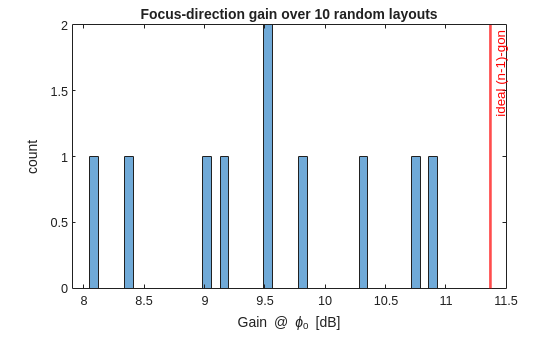

% --- Monte Carlo: random N=9 layouts in the ideal-octagon aperture ---
mc = monte_carlo_layout('N', 9, ...
                        'N_trials', 10, ...
                        'phi_0', 0, ...
                        'R_aperture', 0.0488, ...
                        'd_min', 0.01, ...
                        'd_ideal', 0.04880, ...
                        'verbose', false);


% Strict (>= lambda) separation variant (needs a larger aperture):
% mc_lam = monte_carlo_layout('N', 9, 'N_trials', 300, ...
%                             'R_aperture', 0.5, 'd_min', params.lambda, ...
%                             'verbose', false);

Systematic single-element perturbation: fix 7 of the 8 octagon vertices, and sweep element 2 over a 2D cartesian grid of (dx, dy) offsets from its ideal position. Produces a 3D surface plot for each metric.

% --- Systematic 2D (dx, dy) perturbation of outer element 2 ---
% Produces three 3D surface plots (worst sidelobe, best sidelobe, gain)
% over a cartesian grid of offsets from the element's ideal position.
sw = systematic_perturbation('N', 9, ...
                             'd_ideal', 0.04880, ...
                             'phi_0', 0, ...
                             'moved_idx', 2, ...
                             'dx_list', linspace(-0.03, 0.03, 21), ...
                             'dy_list', linspace(-0.03, 0.03, 21), ...
                             'verbose', true);

  sweep 22/441 (dx=-0.0300, dy=-0.0270): worst=-20.01 best=-26.44 gain=11.63
  sweep 44/441 (dx=-0.0270, dy=-0.0240): worst=-20.16 best=-23.12 gain=11.62
  sweep 66/441 (dx=-0.0240, dy=-0.0210): worst=-20.48 best=-26.10 gain=11.54
  sweep 88/441 (dx=-0.0210, dy=-0.0180): worst=-21.19 best=-24.75 gain=11.50
  sweep 110/441 (dx=-0.0180, dy=-0.0150): worst=-21.46 best=-26.29 gain=11.42
  sweep 132/441 (dx=-0.0150, dy=-0.0120): worst=-20.58 best=-29.57 gain=11.35
  sweep 154/441 (dx=-0.0120, dy=-0.0090): worst=-20.17 best=-29.12 gain=11.38
  sweep 176/441 (dx=-0.0090, dy=-0.0060): worst=-20.54 best=-24.82 gain=11.48
  sweep 198/441 (dx=-0.0060, dy=-0.0030): worst=-20.77 best=-25.44 gain=11.33
  sweep 220/441 (dx=-0.0030, dy=0.0000): worst=-21.96 best=-39.18 gain=11.33
  sweep 242/441 (dx=0.0000, dy=0.0030): worst=-20.86 best=-26.65 gain=11.37


## Geometric Emitter Analysis:

Do a single geometric Perturbation:

% Do a single geometric Perturbation:
N = 8; % Set # of emitters
%rng(1); % Set seed
thetaG = rand(N,1); % Generate N values between (0,1) uniform distribution
thetaG = 2*pi*thetaG; % Scale to 2pi
thetaG = sort(thetaG); % sort ascending
r = [1, 0]; % ideal unit vector facing right
R = [r(1)*cos(thetaG) - r(2)*sin(thetaG), r(1)*sin(thetaG) + r(2)*cos(thetaG)]; % N-1 rotations by the random angles
R = [0 0 ; R]; % Set the center element position
x = R(:,1);
y = R(:,2);
x = 0.04880 * x; % scale by d1 = 0.04880
y = 0.04880 * y; % scale by d1 = 0.04880

%% Start Function
Max_iter = 80; %The algithm goes to step maxiter
eps_dB = -20;
phi_0 = deg2rad(0);
null_phi_list = deg2rad([]);
cone_rad = deg2rad(30);


results1 = perturb_method_v23(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'verbose', false, ...
    'null_phi', null_phi_list, ...
    'show_plots', false, ...
    'show_plot_raw', true, ...
    'show_plot_init', true, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [] )


## Do Monti Carlo (uniform dist.)

% because it seems to glitch without this:
saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';

%% Run setup
Max_iter = 200;
eps_dB = -20;
phi = linspace(0, 2*pi, 1000+1);   % MUST match algorithm
phi(end) = [];   % remove 2π duplicate
nPhi = numel(phi);

run_length = 10; % Number of MontiCarlo instances in the run
N = 9; % Set # of emitters
phi0 = 0;
F_final_store = NaN(run_length, nPhi);   % magnitude
max_SL_all   = cell(run_length, 1);   % cell array of sidelobe vectors
epochs_all   = zeros(run_length, 1);  % store final epoch count
Big_phi_final = NaN(run_length, 1); % store final  
right_bound   = NaN(run_length, 1);  % store right half power beam bound
left_bound   = NaN(run_length, 1);  % store left half power beam bound
main_peak_skew = zeros(run_length, 1);  %store results for diffrence between main beam and focus angle
F_at_focus = NaN(run_length, 1); 
badGeo = false(run_length,1); % setup for recording bad angles

% MontiCarlo Loop
for t = 1:run_length
    thetaG = rand(N,1); % Generate N values between (0,1) uniform distribution
    thetaG = 2*pi*thetaG; % Scale to 2pi
    thetaG = sort(thetaG); % sort ascending
    r = [1, 0]; % ideal unit vector facing right
    R = [r(1)*cos(thetaG) - r(2)*sin(thetaG), r(1)*sin(thetaG) + r(2)*cos(thetaG)]; % N-1 rotations by the random angles
    R = [0 0 ; R]; % Set the center element position
    x = R(:,1);
    y = R(:,2);
    x = 0.04880 * x; % scale by d1 = 0.04880
    y = 0.04880 * y; % scale by d1 = 0.04880

    try
        results = perturb_method_v22(Max_iter, eps_dB, x, y, phi0, ...
            'null_phi', [], ...
            'show_plots', false, ...
            'verbose', false, ...
            'const_null_update', false);

        fprintf('MonteCarlo Run iter %d OK \n', t);
        bw = directivity_met_v2(phi, results.final_function, phi0);

        % Store relevant data
        F_final_store(t, :) = results.final_function;
        max_SL_all{t} = results.max_sidelobe_store;
        epochs_all(t) = results.final_epoch;
        Big_phi_final(t) = results.Big_phi_final;
        right_bound(t) = bw.right_05;
        left_bound(t) = bw.left_05;
        main_peak_skew(t) = results.main_peak_skew(results.final_epoch);
        F_at_focus(t) = results.F_at_phi_0;

    catch ME
        % ---- Mark as bad ----
        badGeo(t) = true;

        fprintf('*** MonteCarlo Run iter %d FAILED ***\n', t );
        fprintf('%s\n', ME.message);

        % ---- Fill safe defaults ----
        F_final_store(t,:) = NaN;
        max_SL_all{t}       = NaN;
        epochs_all(t)      = NaN;
        right_bound(t) = NaN;
        left_bound(t) = NaN;
        F_at_focus(t)    = NaN;

        continue;   
    end        
end

        % NOTE: Remember to double check the above for correct epoch.

%% Convert cell array → padded matrix

%% Trim each sidelobe vector to its actual recorded length
for t = 1:run_length
    v = max_SL_all{t};

    % Valid sidelobes are real numbers between 0 and -200 dB
    validIdx = find(v <= 0 & v >= -200);

    if isempty(validIdx)
        max_SL_all{t} = -40;      % fallback
    else
        lastGood = validIdx(end);
        max_SL_all{t} = v(1:lastGood);
    end
end

% Find longest run (max epoch count)
maxLen = max( cellfun(@length, max_SL_all) );

% Preallocate with NaNs (which surf will skip)
SL_matrix = NaN(run_length, maxLen);

for i = 1:run_length
    L = length(max_SL_all{i});
    SL_matrix(i, 1:L) = max_SL_all{i};
end

%% === Extract final-epoch sidelobe for each instance ===
SL_final = zeros(run_length,1);

for t = 1:run_length
    v = max_SL_all{t};
    if isempty(v)
        SL_final(t) = NaN;    % should not happen, but safe
    else
        SL_final(t) = v(end); % final epoch sidelobe
    end
end

%% ---- Save Monti Carlo data ----
saveFile = fullfile(saveDir, 'MontiCarlo_Geo_uniform.mat');

save(saveFile, ...
    'SL_matrix', ...
    'max_SL_all', ...
    'SL_final', ...
    'epochs_all', ...
    'F_final_store', ...
    'phi', ...
    'badGeo', ...
    'maxLen', ...
    'eps_dB', ...
    'Max_iter', ...
    'right_bound', ...
    'left_bound', ...
    'main_peak_skew', ...
    'Big_phi_final');

## Statistics and Analysis for MC Run Data

%% ---- Load previously saved data ----
% because it seems to glitch without this:
saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';

loadFile = fullfile(saveDir, 'MontiCarlo_Geo_uniform.mat');
load(loadFile);
SL_final
max(SL_final)
min(SL_final)
mean(SL_final)
Max_iter

## Tilt Analysis

%Geometry
d1 = 0.04880;
d2 = 0.04880;
[x,y] = d1d2Convert(d1,d2,9); %Change to 5,9,13 apropriatly

%% Run setup
Max_iter = 200;
eps_dB = -20;
phi = linspace(0, 2*pi, 1000+1);   % MUST match algorithm
phi(end) = [];   % remove 2π duplicate
nPhi = numel(phi);

% Run Algorythm to get amplitudes
results = perturb_method_v22(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'verbose', false, ...
    'null_phi', null_phi_list, ...
    'show_plots', false, ...
    'show_plot_raw', true, ...
    'show_plot_init', true, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [] )

%Nessesary parameters:
amplitudes = results.A_eff;
amplitudes = amplitudes.'; %transpose
%tilt_params.A = amplitudes;
%tilt_params.x = x;
%tilt_params.y = y;
phases = zeros(numel(amplitudes),1).';
phimesh = phi; %same as in method code(defines the plot points)
thetamesh = deg2rad(90); 
axis_id = 1; %
xi = deg2rad(15); % How much we tilt it

% Run tilt Analysis
[F,~] = CalculatePatternTilt(amplitudes, phases, phimesh, thetamesh, [], [], axis_id, xi, x, y)

bw = directivity_met_v2(phi, F, 0)

lab_1 = "Tilted Plot: 1-Beam Method";
%lab_1 = "Final Plot: 1-Beam-1-Null-Const Method";
            % View function graph
            plot_pattern_v5(phi, ...
                F, ...
                'label',lab_1, ...
                'phi_0', phi_0, ...
                'phi_s', [], ...
                'Slobe', [], ...
                'null_phi', [] , ...
                'iter', [], ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', bw.right_05,...
                'bw_edges_left', bw.left_05,...
                'Big_phi', []);

